# 1

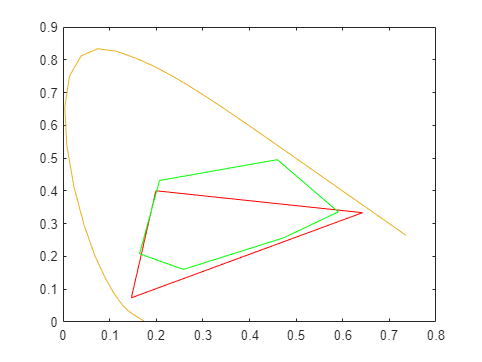

plot_chrom(XYZdell, 'red')
plot_chrom(XYZinkjet, 'green')

# 2

## 2.1

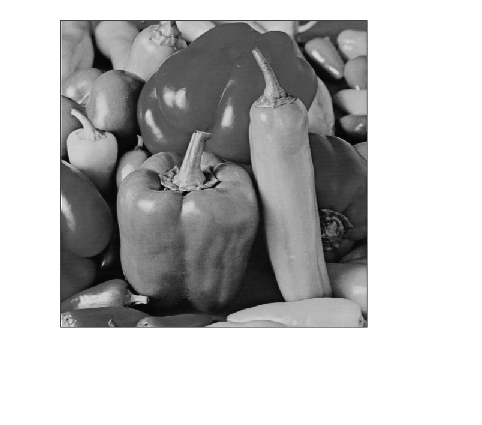

t = Tiff('peppers_color.tif','r');
t2 = Tiff('peppers_gray.tif','r');
pc = read(t);
pg = read(t2);

imshow(pg)

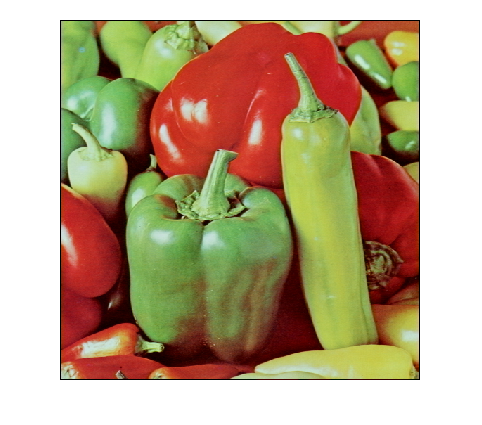

imshow(pc)

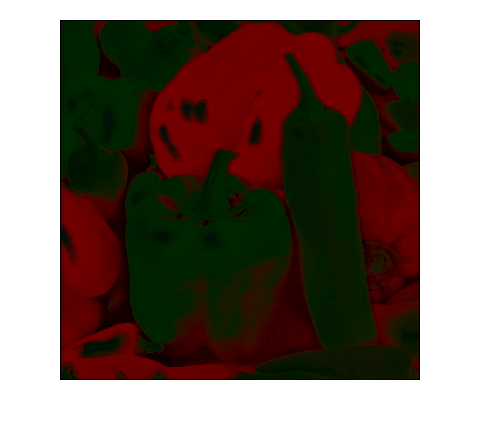

imshow(pc-pg)

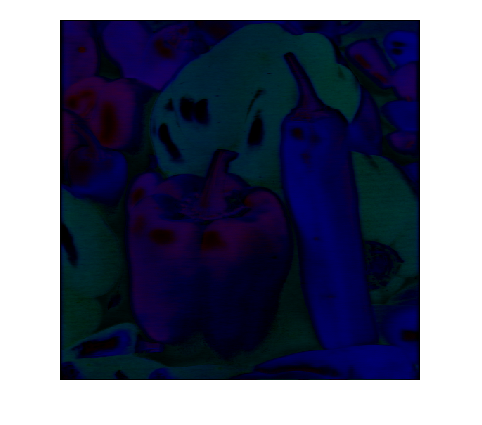

imshow(pg-pc)


mysnr(pg, pc-pg)

ans = -0.7516

mysnr(pg, pg-pc)

ans = -1.6483

### 2.1.1

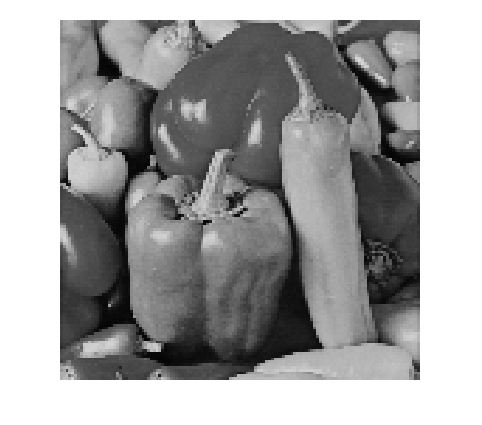

pg_resized1 = imresize(imresize(pg,0.25,'nearest'),4,'nearest');
imshow(pg_resized1)

mysnr(pg, pg-pg_resized1)

ans = 10.4676

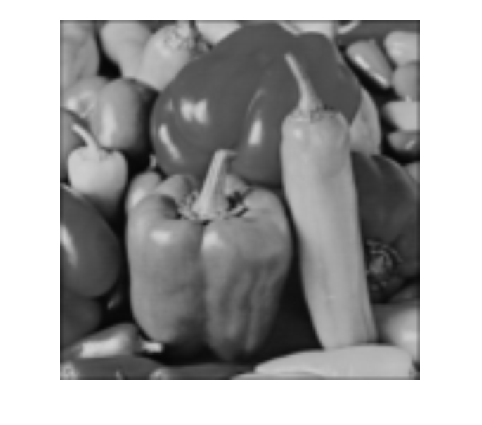


pg_resized2 = imresize(imresize(pg,0.25,'bilinear'),4,'bilinear');
imshow(pg_resized2)

mysnr(pg, pg-pg_resized2)

ans = 9.9089

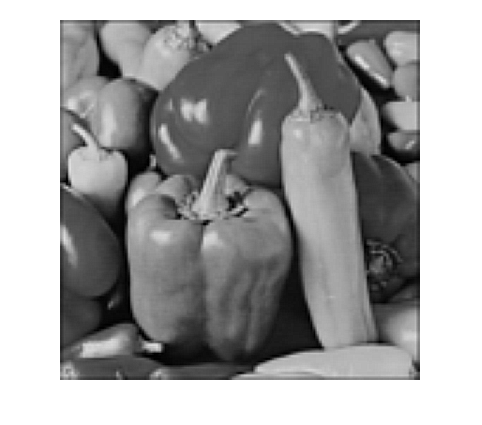

pg_resized2_sharpen = imsharpen(pg_resized2,'Radius',2,'Amount',2);
imshow(pg_resized2_sharpen)

mysnr(pg, pg-pg_resized2_sharpen)

ans = 10.7292

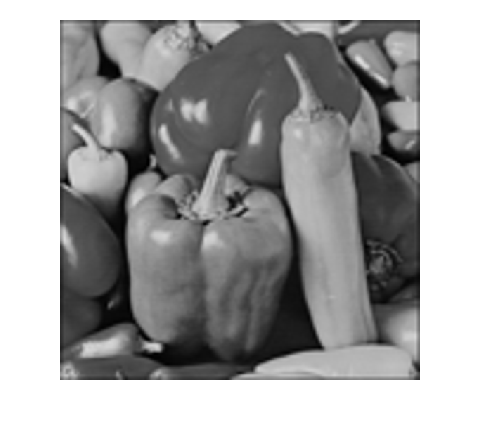


pg_resized3 = imresize(imresize(pg,0.25,'bicubic'),4,'bicubic');
imshow(pg_resized3)

mysnr(pg, pg-pg_resized3)

ans = 10.8879

### 2.1.2

pg = im2double(pg)

pg =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7451    0.5843    0.6078    0.6118    0.6353    0.6510    0.6588    0.6588    0.6588    0.6588    0.6667    0.6745    0.6824    0.6784    0.6784    0.6824    0.6784    0.6706    0.6549    0.6314    0.6235    0.6275    0.6039    0.5804    0.5725    0.5569    0.5490    0.5333    0.5373    0.5255    0.5098    0.5098    0.5176    0.5176    0.5098    0.5176    0.5216    0.5020    0.5059    0.5020    0.4824    0.4627    0.4275    0.3961    0.3608    0.3294    0.2902    0.2549    

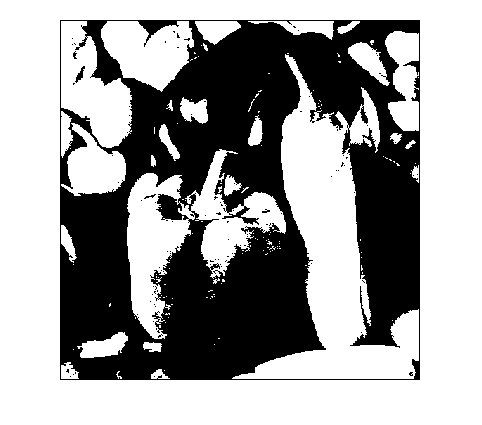


pg_thres = pg >= 0.5;
imshow(pg_thres)

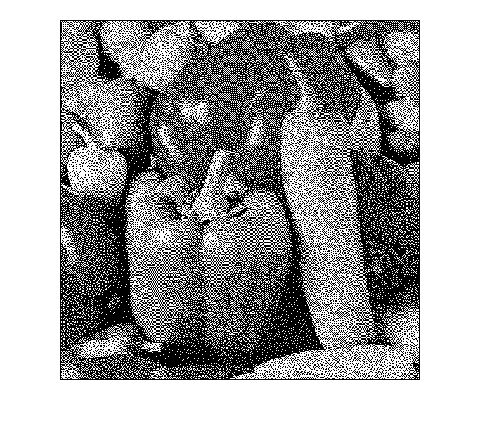

pg_dither = dither(pg);
imshow(pg_dither)


mysnr(pg, pg - double(pg_thres))

ans = 2.9721

mysnr(pg, pg - double(pg_dither))

ans = 0.4112

## 2.2

img(:,:,1) = (pc(:,:,1)/256) >= 0.5;

Unable to perform assignment because the size of the left side is 300-by-450 and the size of the right side is 512-by-512.

img(:,:,2) = (pc(:,:,2)/256) >= 0.5;
img(:,:,3) = (pc(:,:,3)/256) >= 0.5;

img1(:,:,1) = dither(im2double(pc(:,:,1)));
img1(:,:,2) = dither(im2double(pc(:,:,2)));
img1(:,:,3) = dither(im2double(pc(:,:,3)));

imshow(im2double(img))
imshow(im2double(img1))

img_lab=rgb2lab(im2uint8(img));
img1_lab=rgb2lab(im2uint8(img1));

pc_lab=rgb2lab(pc);

dE = euclidean_distance_lab_nxnx3(img_lab, pc_lab);
dE1 = euclidean_distance_lab_nxnx3(img1_lab, pc_lab);
max(max(dE))
mean(mean(dE))
max(max(dE1))
mean(mean(dE1))

# 3

snr_filter(double(pg_thres), pg - double(pg_thres))
snr_filter(double(pg_dither), pg - double(pg_dither))

f = MFTsp(15,0.0847,500);

% thresholded picture
img_hvs(:,:,1) = conv2(im2uint8(img(:,:,1)),f,'same');
img_hvs(:,:,2) = conv2(im2uint8(img(:,:,2)),f,'same');
img_hvs(:,:,3) = conv2(im2uint8(img(:,:,3)),f,'same');

img_hvs(:,:,1) = (img_hvs(:,:,1) > 0) .* img_hvs(:,:,1);
img_hvs(:,:,2) = (img_hvs(:,:,2) > 0) .* img_hvs(:,:,2);
img_hvs(:,:,3) = (img_hvs(:,:,3) > 0) .* img_hvs(:,:,3);

img_hvs_lab = rgb2lab((img_hvs)/256);

dE = euclidean_distance_lab_nxnx3(img_hvs_lab, pc_lab);

max(max(dE))
mean(mean(dE))

% Dithered picture
img_hvs(:,:,1) = conv2(im2uint8(img1(:,:,1)),f,'same');
img_hvs(:,:,2) = conv2(im2uint8(img1(:,:,2)),f,'same');
img_hvs(:,:,3) = conv2(im2uint8(img1(:,:,3)),f,'same');

img_hvs(:,:,1) = (img_hvs(:,:,1) > 0) .* img_hvs(:,:,1);
img_hvs(:,:,2) = (img_hvs(:,:,2) > 0) .* img_hvs(:,:,2);
img_hvs(:,:,3) = (img_hvs(:,:,3) > 0) .* img_hvs(:,:,3);

img_hvs_lab = rgb2lab((img_hvs)/256);

dE = euclidean_distance_lab_nxnx3(img_hvs_lab, pc_lab);

max(max(dE))
mean(mean(dE))

# 4

## 4.1

pc_r1 = imresize(imresize(pc,0.25,'nearest'),4,'nearest');
pc_r2 = imresize(imresize(pc,0.25,'bilinear'),4,'bilinear');
pc_r3 = imresize(imresize(pc,0.25,'bicubic'),4,'bicubic');

pc_r1_xyz = rgb2xyz(pc_r1);
pc_r2_xyz = rgb2xyz(pc_r2);
pc_r3_xyz = rgb2xyz(pc_r3);

ls =  [95.05, 100, 108.9]

ls =    95.0500  100.0000  108.9000



im_format = 'xyz'

im_format = 'xyz'


ppi = 91.79

ppi = 91.7900

d = 24

d = 24


im_scielab_n = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r1_xyz, ls, im_format)

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

Error in deltaLab (line 58)
  d = reshape(d, m);

Error in scielab (line 201)
    result = deltaLab(result, result2, whitepoint);    

im_scielab_bl = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r2_xyz, ls, im_format)
im_scielab_bc = scielab(ppi*d*1.5574,rgb2xyz(pc), pc_r3_xyz, ls, im_format)

mean(mean(im_scielab_n))
mean(mean(im_scielab_bl))
mean(mean(im_scielab_bc))

## 4.2

sampPerDeg = ppi*d*1.5574;
SCIELAB_STD(sampPerDeg, c1)
SCIELAB_STD(sampPerDeg, c2)
SCIELAB_STD(sampPerDeg, c3)
SCIELAB_STD(sampPerDeg, c4)
SCIELAB_STD(sampPerDeg, c5)

imshow(c1)
imshow(c2)
imshow(c3)
imshow(c4)
imshow(c5)

# 5

## a

im2double(pg)
d1 = distort1(im2double(pg))
d2 = distort2(im2double(pg))

mysnr(im2double(pg), im2double(pg) - d1)
mysnr(im2double(pg), im2double(pg) - d2)

[s1,s1_map]=ssim(d1,im2double(pg))
imshow(s1_map)
[s1,s1_map2]=ssim(d2,im2double(pg))
% imshow(s1_map2)


## b

% distortion
dist1 = im2double(pg)+0.2*(rand(size(im2double(pg)))-0.5)

% gaussian filter
f = fspecial('gauss',21,10)
dist2 = conv2(im2double(pg),f,'same');

imshow(dist1)
imshow(dist2)

mysnr(im2double(pg), im2double(pg) - dist1)
mysnr(im2double(pg), im2double(pg) - dist2)

ssim(dist1,im2double(pg))
ssim(dist2,im2double(pg))

function d1 = distort1(d1)
    for i = 2:511
        % even number
        if mod(i,2) == 0
            d1(2:511,i) = d1(2:511,i) + 0.1;
        else
            d1(2:511,i) = d1(2:511,i) - 0.1;
        end
    end
end

function d1 = distort2(d1)
    for i = 2:511
        % even number
        if i <= 255
            d1(i,2:511) = d1(i,2:511) + 0.1;
        else
            d1(i,2:511) = d1(i,2:511) - 0.1;
        end
    end
end


function res = SCIELAB_STD(sampPerDeg, c)
    c_xyz = rgb2xyz(c);
    temp = scielab(sampPerDeg, c_xyz);
    res = std2(temp(:,:,1)) + std2(temp(:,:,2)) + std2(temp(:,:,3));
end